Function

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;


To integrate function from 0 to 0.8

format short

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000



q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with trapezoidal rule applied to each unequal segment

% data (unequal segments) used to integration with trapezoidal rule
x = [0 0.12 0.22 0.32 0.36 0.4 0.44 0.54 0.64 0.7 0.8];
y = f(x);

ns= length(x) - 1

ns = 10


figure
color = ['g', 'y'];

color = 'gy'

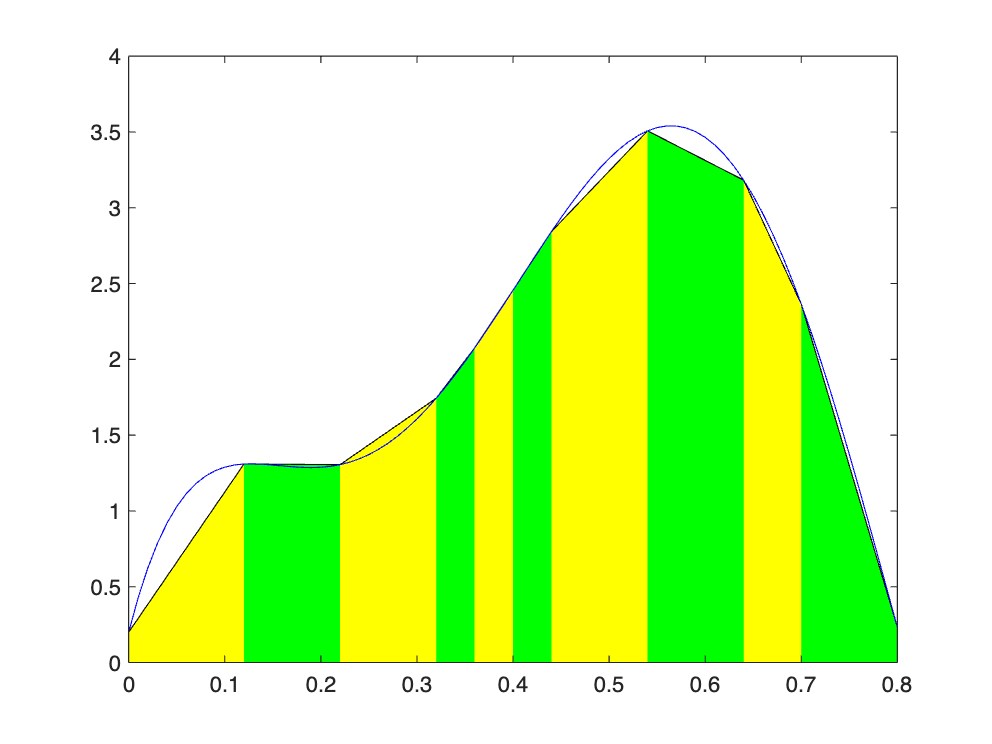


for i = 1:ns
    area(x(i:i+1), y(i:i+1), 'FaceColor', color(mod(i, 2)+1),'EdgeColor','black', 'LineStyle','-')
        hold on
end
plot(xx, yy, 'b-')